# Data

load("Calibration_Parameters.mat")
gps_driving = readtable('data_driving_gps.csv');

imu_driving = readtable('data_driving_imu.csv');


mag_x_driving = imu_driving.MagField_magnetic_field_x;
mag_y_driving = imu_driving.MagField_magnetic_field_y; 

## CALIBRATION OF THE DRIVING MAGNETIC FIELD

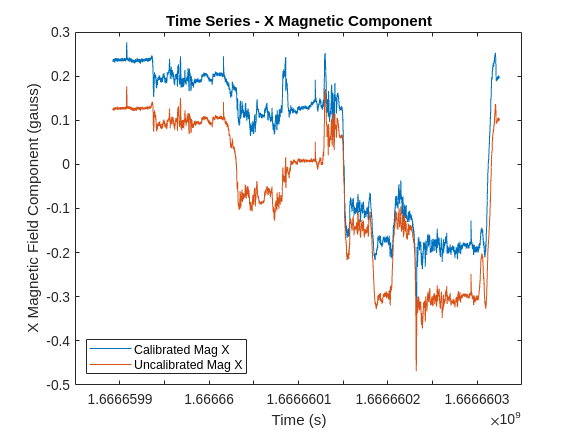

time = imu_driving.Time;
mag_calibrated_driving = Mc*([mag_x_driving';mag_y_driving'] -Bc);
plot(time,mag_calibrated_driving(1,:),"DisplayName","Calibrated Mag X");
hold on
plot(time,mag_x_driving,"DisplayName","Uncalibrated Mag X");
hold off
xlabel("Time (s)")
ylabel("X Magnetic Field Component (gauss)")
title("Time Series - X Magnetic Component")
legend('location','southwest')

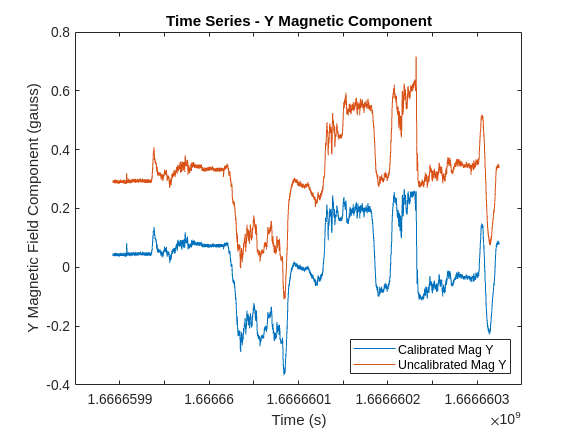


plot(time,mag_calibrated_driving(2,:),"DisplayName","Calibrated Mag Y");
hold on
plot(time,mag_y_driving,"DisplayName","Uncalibrated Mag Y");
hold off

xlabel("Time (s)")
ylabel("Y Magnetic Field Component (gauss)")
title("Time Series - Y Magnetic Component")
legend('location',"southeast")

## RAW YAW

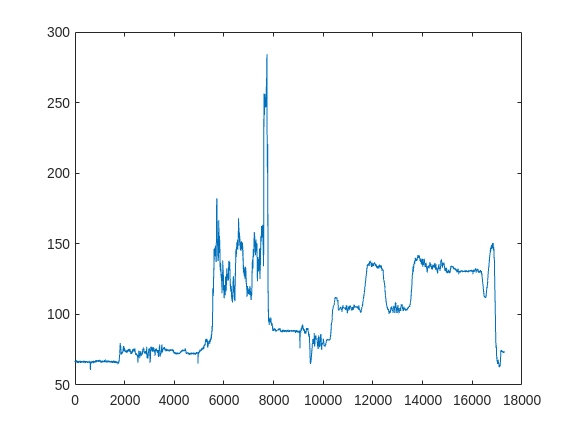

len = length(mag_x_driving);
%r = (mag_x_driving.^2 + mag_y_driving.^2).^0.5;
raw_yaw = unwrap(atan2(mag_y_driving,mag_x_driving));
%plot((180/pi)*raw_yaw)

% for i = 1:len
%     if mag_y >= 0
%         raw_yaw(i) = -raw_yaw(i);
%     end
% end
raw_yaw = (180/pi)*raw_yaw;
plot(raw_yaw)

## CALIBRATED YAW FROM MAGNETOMETER

len = length(mag_x_driving);
yaw = zeros(len,1);
%r = (mag_calibrated_driving(1,:).^2 + mag_calibrated_driving(2,:).^2).^0.5;
%yaw = acos(mag_calibrated_driving(1,:)./r)
yaw = unwrap(atan2(-mag_calibrated_driving(2,:),mag_calibrated_driving(1,:)));
% for i = 1:len
%     if mag_calibrated_driving(2,i) >= 0
%         yaw(i) = -yaw(i);
%     end
% end
yaw = (180/pi)*yaw;
yaw = yaw-90;

## YAW FROM IMU THROUGH EKF

qx = imu_driving.IMU_orientation_x;
qy = imu_driving.IMU_orientation_y;
qz = imu_driving.IMU_orientation_z;
qw = imu_driving.IMU_orientation_w;

quat = [qw qx qy qz];
eul = quat2eul(quat);
len_eul = length(eul);
yaw_EKF = (180/pi)*unwrap(eul(:,1));

## PLOTTING YAW

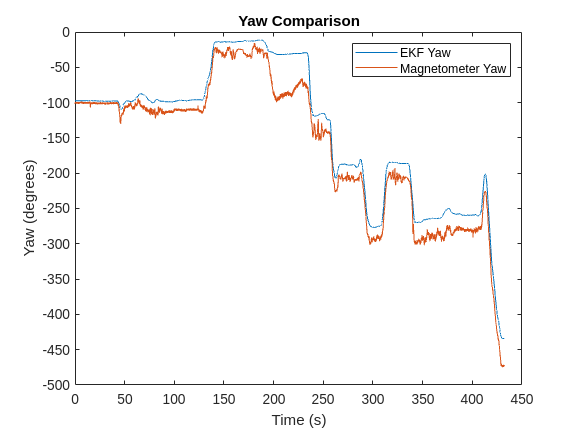

time = imu_driving.Time;
time = time - time(1);
plot(time,yaw_EKF,"DisplayName","EKF Yaw")
hold on
plot(time,yaw,"DisplayName","Magnetometer Yaw")
xlabel("Time (s)")
ylabel("Yaw (degrees)")
title("Yaw Comparison")
legend
hold off

## YAW FROM THE GYROSCOPE

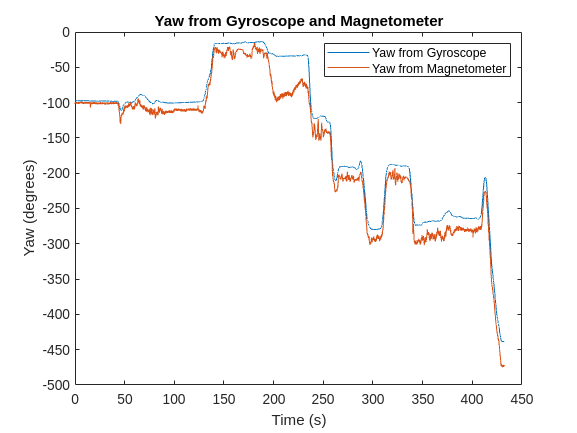

gyro_z = rad2deg(imu_driving.IMU_angular_velocity_z);
gyro_yaw = (1/40)*cumtrapz(gyro_z) + yaw_EKF(1);
plot(time,gyro_yaw,"DisplayName","Yaw from Gyroscope")
hold on
plot(time,yaw,"DisplayName","Yaw from Magnetometer")
%plot(time,yaw_EKF,"DisplayName","yaw from IMU")
hold off
legend
xlabel("Time (s)")
ylabel("Yaw (degrees)")
title("Yaw from Gyroscope and Magnetometer")

## LOW PASS FILTERING MAGNETOMETER YAW

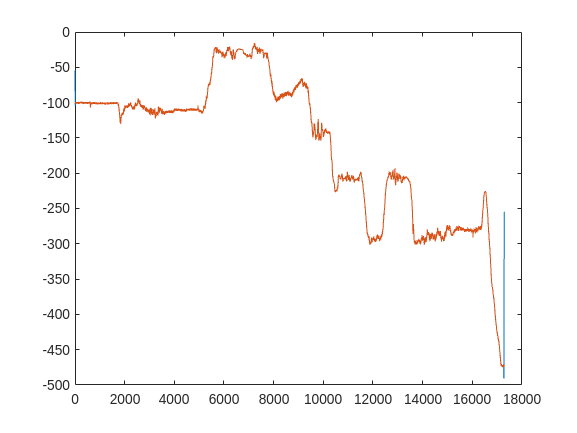

yaw_LF = lowpass(yaw,0.00001,40);
plot(yaw_LF)
hold on
plot(yaw)
hold off

## HIGH PASS FILTERING THE GYRO YAW

gyro_yaw_HF = highpass(gyro_yaw,0.01,40);
gyro_yaw_HF = gyro_yaw_HF - gyro_yaw_HF(1) + gyro_yaw(1)

gyro_yaw_HF =   -97.4620
  -97.4714
  -97.4801
  -97.4881
  -97.4974
  -97.5071
  -97.5178
  -97.5266
  -97.5345
  -97.5442


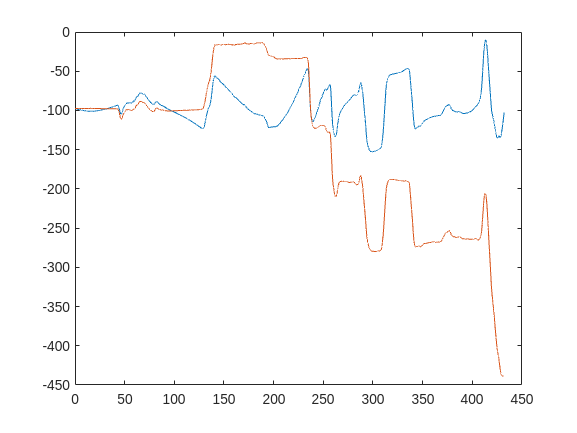

plot(time,gyro_yaw_HF)
hold on
plot(time,gyro_yaw)
hold off

## COMPLEMENTARY FILTER

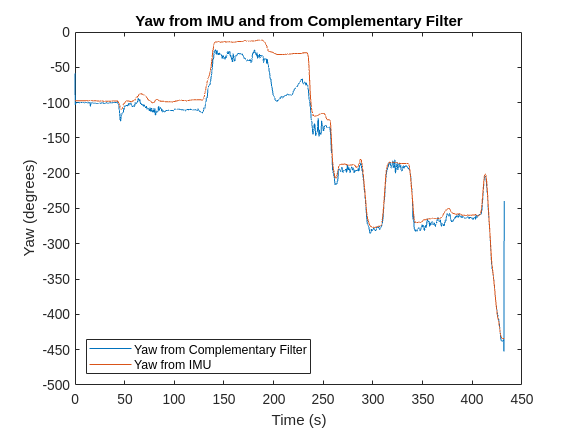

alpha = 0.1;
fused_yaw = (alpha)*gyro_yaw_HF +(1-alpha)*yaw_LF';
plot(time,fused_yaw,"DisplayName","Yaw from Complementary Filter")
hold on
plot(time,yaw_EKF,"DisplayName","Yaw from IMU")
hold off
xlabel("Time (s)")
ylabel("Yaw (degrees)")
title("Yaw from IMU and from Complementary Filter")
legend('location','southwest')

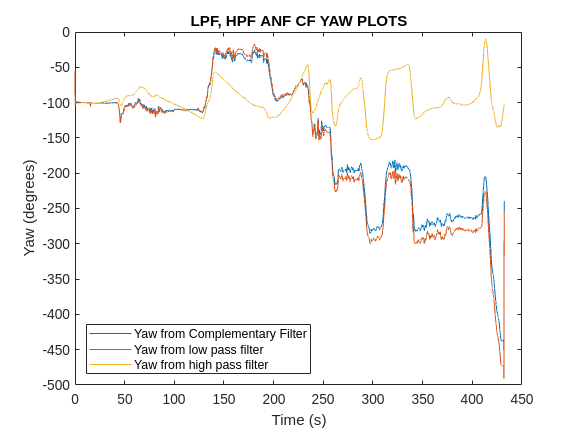

% PLOTTING LPF, HPF AND CF YAWS TOGETHER
plot(time,fused_yaw,"DisplayName","Yaw from Complementary Filter")
hold on
plot(time,yaw_LF, "DisplayName","Yaw from low pass filter")
plot(time, gyro_yaw_HF, "DisplayName","Yaw from high pass filter")
xlabel("Time (s)")
ylabel("Yaw (degrees)")
title("LPF, HPF ANF CF YAW PLOTS")
legend('location','southwest')

## FORWARD VELOCITY ESTIMATE

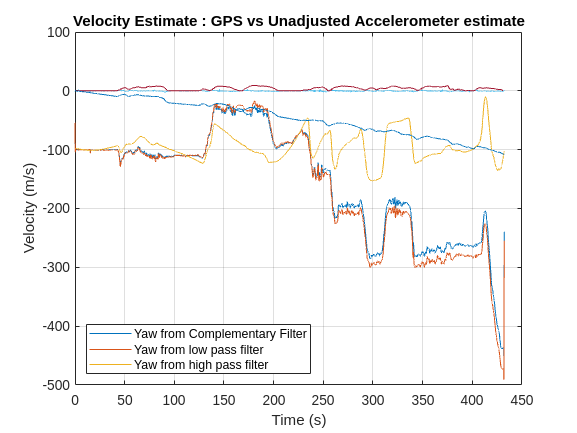

acc_x = imu_driving.IMU_linear_acceleration_x;
acc_y = imu_driving.IMU_linear_acceleration_y;
acc_z = imu_driving.IMU_linear_acceleration_z;

plot(time, acc_x)
xlabel("Time (s)")
ylabel("Acceleration (m/s)")
title("Plot of forward acceleration")
vel_x_acc = (1/40)*cumtrapz(acc_x);
plot(time,vel_x_acc)
plot(time,acc_x)
grid on
% EXTRACTING GPS DATA
time_gps = gps_driving.Time;
time_gps = time_gps - time_gps(1);
utm_E = gps_driving.UTM_easting;
utm_N = gps_driving.UTM_northing;
utm_E = utm_E - utm_E(1);
utm_N = utm_N - utm_N(1);
utm_E = interp1(time_gps,utm_E,time);
utm_N = interp1(time_gps,utm_N,time);

% GETTING SPEED FROM GPS COORDINATES
vel_x_gps = zeros(len,1);
vel_y_gps = zeros(len,1);
speed_gps = zeros(len,1);
vel_x_gps(1) = (utm_E(2)-utm_E(1))*(time(2)-time(1));        % Forward difference approximation at the beginning
vel_y_gps(1) = (utm_N(2)-utm_N(1))*(time(2)-time(1));
speed_gps(1) = [vel_x_gps(1)^2 + vel_y_gps(1)^2]^0.5;
vel_x_gps(len)= [utm_E(len) - utm_E(len-1)]/(time(len)-time(len-1));      % Backward difference approximation at the ending
vel_y_gps(len)= [utm_N(len) - utm_N(len-1)]/(time(len)-time(len-1));
speed_gps(len) = [vel_x_gps(len)^2 + vel_y_gps(len)^2]^0.5;
for i = 2:len-1
    dt1 = time(i+1)-time(i);
    dt2 = time(i)-time(i-1);
    % Central difference approximation for all the points in contained in between the start and the end points
    vel_x_gps(i) = (utm_E(i+1)-utm_E(i-1))/(dt1+dt2);         
    vel_y_gps(i) = (utm_N(i+1)-utm_N(i-1))/(dt1+dt2);
    speed_gps(i) = (vel_x_gps(i)^2 + vel_y_gps(i)^2)^0.5;
end
plot(time,speed_gps,"DisplayName","GPS Velocity Estimate")
hold on
plot(time,vel_x_acc,"DisplayName","Unadjusted Accelerometer Velocity Estimate")
hold off
legend('location','southwest')
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Velocity Estimate : GPS vs Unadjusted Accelerometer estimate")

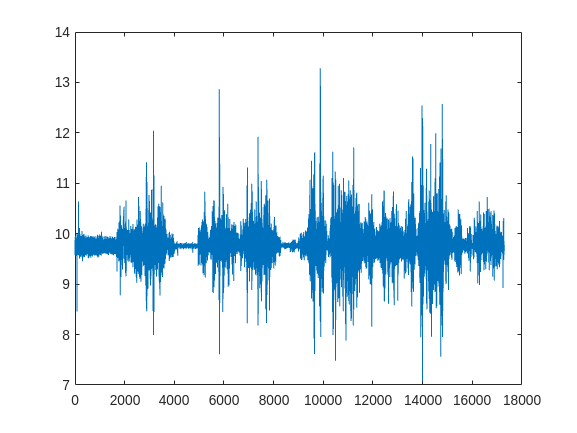



% Finding sections where the acceleration magnitude drops below a certain threshold

net_acc = (acc_x.^2 + acc_y.^2 + acc_z.^2).^0.5;
plot(net_acc)

%acc = net_acc;

% Program block to find the sections of the accelerations corresponding to
% stationary car conditions. 
acc = acc_x;
bias = [];
c = 0;
flag = 0;
start_time = [];
end_time = [];
for i = 1:numel(acc)
    if abs(acc(i))<0.5 
        c = c + 1;
        if flag == 0
            start_time(end+1) = i;
            flag = 1;
            %disp("flag set 1")
        end
        if c>=200
            flag = 11;
        end
    elseif flag == 11
        c = 0;
        flag = 0;
        disp("Flag 11 condition - adding to end time")
        end_time(end+1) = i-1;
        bias(end+1) = mean(acc(start_time(end):end_time(end)));
    elseif flag == 1
        c = 0;
        flag = 0;
        %disp("Deleting end of start time")
        length(start_time);
        start_time(end) = [];
%         if isempty(end_time)
%             continue
%         else 
%             length(end_time);
%             end_time(end) = [];
%         end
    else 
       % flag = 0
       continue
    end
end

Flag 11 condition - adding to end time
Flag 11 condition - adding to end time
Flag 11 condition - adding to end time
Flag 11 condition - adding to end time


% Correcting acceleration in the regions between the sections

for i = 1:numel(end_time)
    i
    curr_bias = mean(acc_x(start_time(i):end_time(i)))
    acc_x(start_time(i):end_time(i)) = 0;
%     disp("Making acc zero in the section")
%     plot(acc_x(start_time(i):end_time(i)))
%     figure;
%     plot(acc_x(end_time(i)+1:start_time(i+1)-1))
%     hold on
    if length(start_time)>i
    acc_x(end_time(i)+1:start_time(i+1)-1) = acc_x(end_time(i)+1:start_time(i+1)-1) - curr_bias;  % Subtracting the mean
%     plot(acc_x(end_time(i)+1:start_time(i+1)-1))
%     hold off
%     disp("Subtraction successful")
    else 
     acc_x(end_time(i)+1:end) = acc_x(end_time(i)+1:end) - curr_bias   
    end
end

i = 1

curr_bias = -0.1935

i = 2

curr_bias = -0.2204

i = 3

curr_bias = -0.1425

i = 4

curr_bias = -0.2986

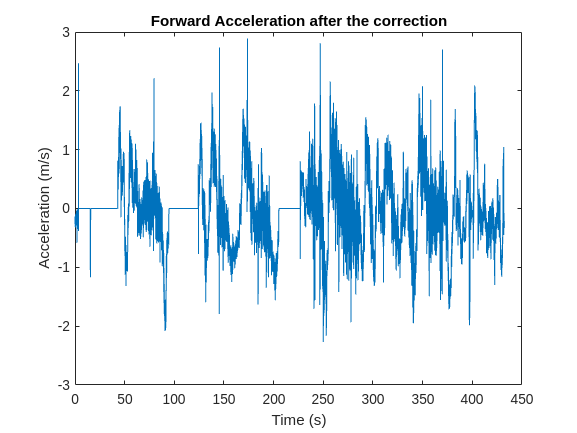

acc_x(end_time(end)+1:end) = acc_x(end_time(end)+1:end) - 0.05;
% Integrating acceleration 
plot(time, acc_x)
xlabel("Time (s)")
ylabel("Acceleration (m/s)")
title("Forward Acceleration after the correction")

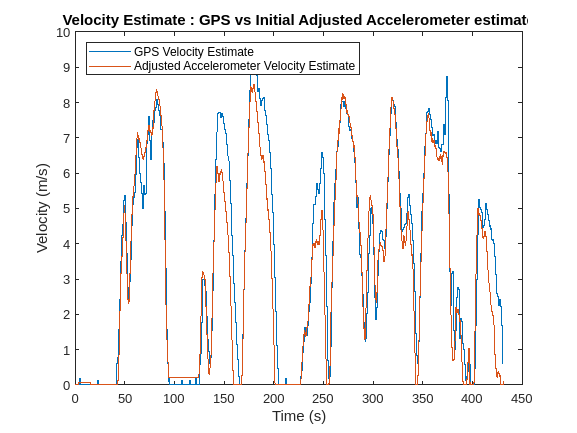

speed_acc_corr = zeros(numel(acc_x),1);
sum = 0;
for i = 2:numel(acc_x)
    sum = sum + 0.5*(acc_x(i) + acc_x(i-1))*(1/40);
    if sum < 0
        sum  = sum - 0.5*(acc_x(i) + acc_x(i-1))*(1/40);  % Bringing back sum to its earlier value
        speed_acc_corr(i) = 0;
    else 
        speed_acc_corr(i) = sum;
    end
end
figure
plot(time,speed_gps,"DisplayName","GPS Velocity Estimate")
hold on
plot(time,speed_acc_corr,"DisplayName","Adjusted Accelerometer Velocity Estimate")
hold off
legend('location','northeast')
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Velocity Estimate : GPS vs Initial Adjusted Accelerometer estimate")
legend('location','northwest')

## DEAD RECKONING

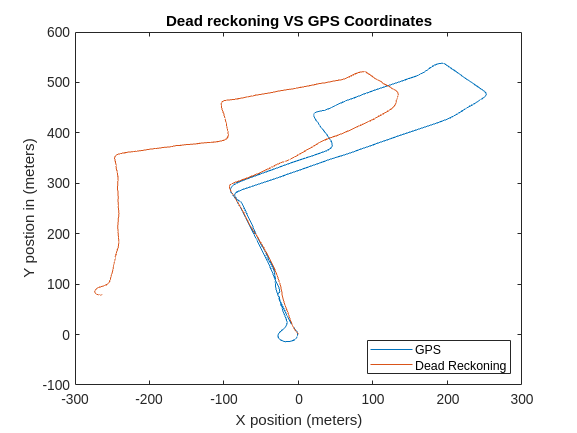


xpos = zeros(numel(acc_x),1);
ypos = zeros(numel(acc_x),1);
fused_yaw;

% utm_E_acc = vel_x_acc_corr.*cos(fused_yaw);
% utm_N_acc = vel_x_acc_corr.*sin(fused_yaw);

vel_x_imu = speed_acc_corr.*cosd(fused_yaw);
vel_y_imu = speed_acc_corr.*sind(fused_yaw);

xpos = (1/40)*cumsum(vel_x_imu);
ypos = -(1/40)*cumsum(vel_y_imu);

% for i = 2 : numl(acc_x)
%     xpos(i) = xpos(i-1) + (1/40)*speed_acc_corr(i)*cos(fused_yaw(i));
%     utm_N_acc(i) = utm_N_acc(i-1) + (1/40)*speed_acc_corr(i)*sin(fused_yaw(i));
% end

% Plotting the final dead reckoning plot
plot(utm_E,utm_N,"DisplayName","GPS")
hold on
plot(xpos,ypos,"DisplayName","Dead Reckoning")
hold off
xlabel("X position (meters)")
ylabel("Y postion in (meters)")
title("Dead reckoning VS GPS Coordinates")
legend('location','southeast')

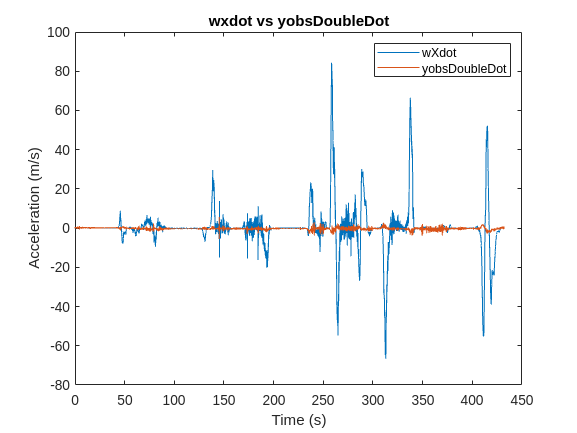

wxdot = gyro_z.*vel_x_imu;
yobsdd = acc_y;

plot(time,wxdot,"DisplayName","wXdot")
hold on
plot(time,yobsdd,"DisplayName", "yobsDoubleDot")
hold off
legend
xlabel("Time (s)")
ylabel("Acceleration (m/s)")
title("wxdot vs yobsDoubleDot")

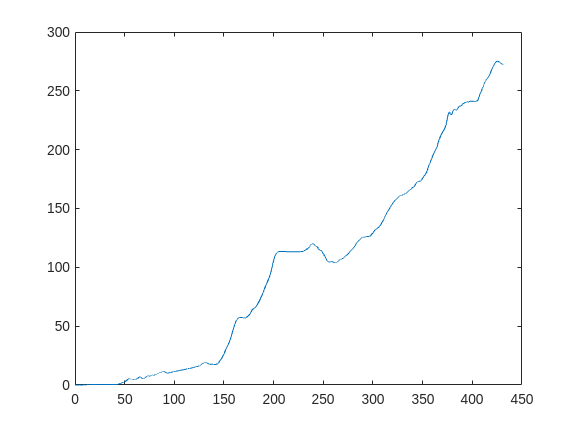

% Calculating the deviation of IMU from GPS
    vector_dev = [(xpos - utm_E)'; (ypos-utm_N)'];
    dev = vecnorm(vector_dev);
    plot(time, dev)

    accumulated_dev = cumsum(dev);
    accumulated_dev_10sec = accumulated_dev(400)

accumulated_dev_10sec = 19.5920